# Instrumentation, measurement methods, errors in the instrumentation

This script illustrates the concepts of:

- characteristic of an ideal instrument

- characteristic of a real instrument

- ideal quantization for uniform rounding

- quantization not ideal for uniform rounding

- custom quantization *

- gain, offset, integral nonlinearity and relative errors

- uncertainty of a measure

In particular, the calculations are shown to obtain the graphical representations suitable for a better visual understanding which therefore make the learning less mechanical and more practical.

* explained below

## Characteristic of an ideal instrument

clf %clear figure
disp('======================================');

disp('Characteristic of an ideal instrument');

Caratteristica di uno strumento ideale


disp('======================================');

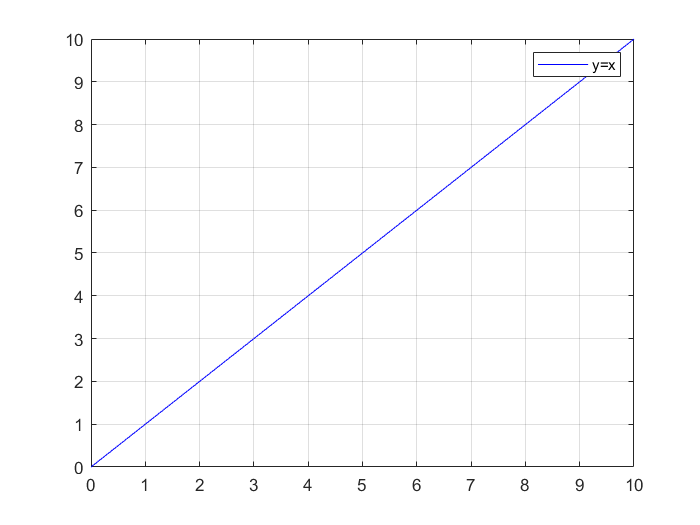

syms x %variable
y=x; %function
fplot(y, 'blue') %graph
hold on %holds the graph just plotted
grid on %adds the grid
axis([0 10 0 10]) %range of vision of the axes
legend('y=x') %legend

## Characteristic of a real instrument

The differences with the ideal characteristic previously illustrated are visible

clf %clear figure
disp('=====================================');

disp('Characteristic of a real instrument');

Caratteristica di uno strumento reale


disp('=====================================');

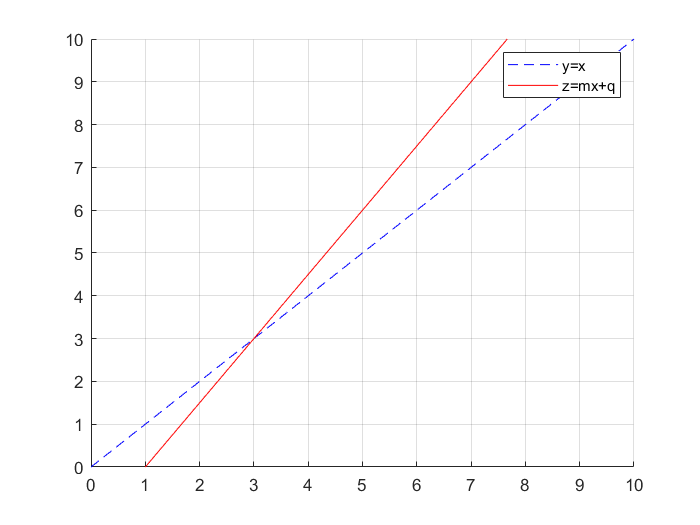

m=input('Enter the angular coefficient of the line (different from 1 as it is a real instrument): ');
q=input('Enter the ordinate at the origin (different from 0 as it is a real instrument): ');
syms x %variable
hold on %plot on a single figure
grid on %adds the grid
y=x; %function
fplot(y,'blue --') %graph
z=m*x+q; %function
fplot(z, 'red') %graph
axis([0 10 0 10]) %range of vision of the axes
legend('y=x','z=mx+q') %legend

## Ideal quantization for uniform rounding

clf %clear figure
disp('=================================================');

disp('Ideal quantization for uniform rounding');

Quantizzazione ideale per arrotondamento uniforme


disp('=================================================');

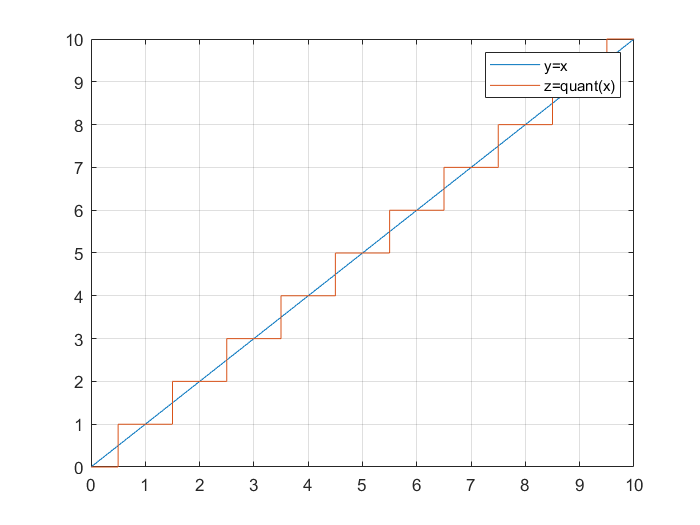

Q=input('Enter the quantization step value: '); %input Q
syms x %variable
a=-Q/2; %far left
b=Q/2; %far right
c=0; %value
y=x; %function
z=piecewise(a+0<x<b+0, c+0, a+Q<x<b+Q, c+Q, a+2*Q<x<b+2*Q, c+2*Q, a+3*Q<x<b+3*Q, c+3*Q, a+4*Q<x<b+4*Q, c+4*Q, a+5*Q<x<b+5*Q, c+5*Q, a+6*Q<x<b+6*Q, c+6*Q, a+7*Q<x<b+7*Q, c+7*Q, a+8*Q<x<b+8*Q, c+8*Q, a+9*Q<x<b+9*Q, c+9*Q, a+10*Q<x<b+10*Q, c+10*Q); %quantization
fplot(y) %graph
hold on %holds the graph just plotted
grid on %adds the grid
zoom(0.1) %zoom in if argument > 1, zoom out if argument < 1
axis([0 10*Q 0 10*Q]) %range of vision of the axes
fplot(z) %graph
hold on %holds the graph just plotted
grid on %adds the grid
zoom(0.1) %zoom in if argument > 1, zoom out if argument < 1
axis([0 10*Q 0 10*Q]) %range of vision of the axes
legend('y=x','z=quant(x)') %legend

## Quantization not ideal for uniform rounding

clf %clear figure
disp('=====================================================');

disp('Quantization not ideal for uniform rounding');

Quantizzazione non ideale per arrotondamento uniforme


disp('=====================================================');

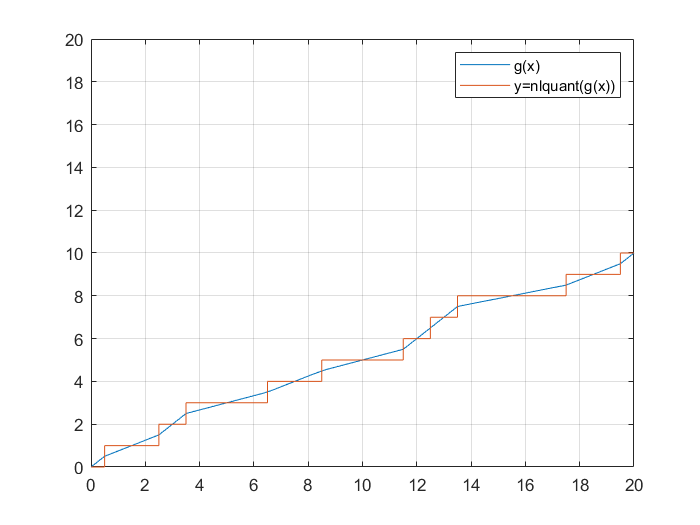

Q=input('Enter the quantization step value: '); %input Q
syms x %variable
a=-Q/2; %far left
b=Q/2; %far right
c=0; %value
y=piecewise(a+0<x<b+0, x, a+Q<x<b+2*Q, 1/2*x+Q/4, a+3*Q<x<b+3*Q, x-Q, a+4*Q<x<b+6*Q, 1/3*x+4*Q/3, a+7*Q<x<b+8*Q, 1/2*x+Q/4, a+9*Q<x<b+11*Q, 1/3*x+5*Q/3, a+12*Q<x<b+12*Q, x-6*Q, a+13*Q<x<b+13*Q, x-6*Q, a+14*Q<x<b+17*Q, 1/4*x+33*Q/8, a+18*Q<x<b+19*Q, 1/2*x-Q/4, a+20*Q<x<b+20*Q, x-10*Q); %function
z=piecewise(a+0<x<b+0, c+0, a+Q<x<b+2*Q, c+Q, a+3*Q<x<b+3*Q, c+2*Q, a+4*Q<x<b+6*Q, c+3*Q, a+7*Q<x<b+8*Q, c+4*Q, a+9*Q<x<b+11*Q, c+5*Q, a+12*Q<x<b+12*Q, c+6*Q, a+13*Q<x<b+13*Q, c+7*Q, a+14*Q<x<b+17*Q, c+8*Q, a+18*Q<x<b+19*Q, c+9*Q, a+20*Q<x<b+20*Q, c+10*Q); %quantization
fplot(y) %graph
hold on %holds the graph just plotted
grid on %adds the grid
zoom(0.1) %zoom in if argument > 1, zoom out if argument < 1
axis([0 20*Q 0 20*Q]) %range of vision of the axes
fplot(z) %graph
hold on %holds the graph just plotted
grid on %adds the grid
zoom(0.1) %zoom in if argument > 1, zoom out if argument < 1
axis([0 20*Q 0 20*Q]) %range of vision of the axes
legend('g(x)','y=nlquant(g(x))') %legend

## Custom quantization

The user enters the quantization step Q, the number of intervals on the abscissa axis and their value to obtain a generic piecewise linear g (x) function and its corresponding quantization. If a value equal to that of the quantization step Q is given to all the intervals, a linear quantization will be obtained; on the other hand, if even a single interval should have any value other than that of the quantization step Q, a non-linear quantization will be obtained. Furthermore, the horizontal steps represent the approximate values (through quantization in fact) of the different segments that make up the piecewise linear function.

clf %clear figure
disp('=============================');

disp('Custom quantization');

Quantizzazione personalizzata


disp('=============================');

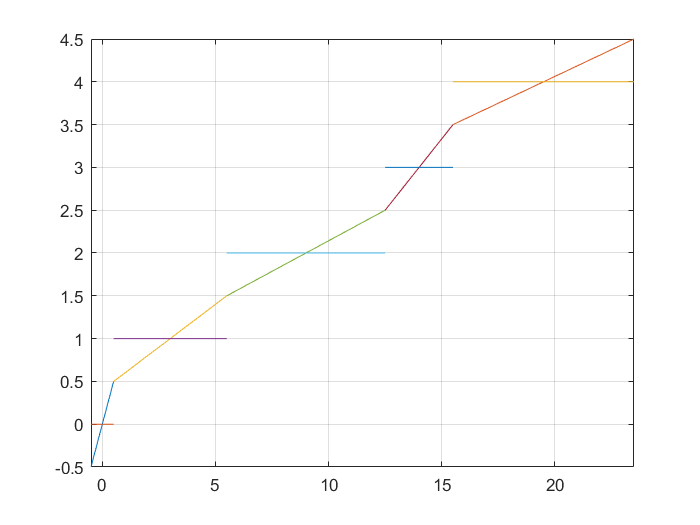

syms x %variable
Q=input('Enter the quantization step value: '); %quantization step Q
n=input('Enter the number of intervals on the abscissa axis: '); %length n vector of the intervals
w=0;
i=1;
while i<=n
    V(i)=input('Range value: '); %if the value of all the intervals is equal to that of Q we have an ideal quantization
    if V(i)~=Q
        w=w+1;
    end
    i=i+1;
end
i=1;
while i<=n
    j=i;
    d=0;
    while (3<i) && (i<=n)
        d=d+V(i-1)+V(i-2);
        i=i-2;
    end
    switch i
        case 1
            d=d+0;
        case 2
            d=d+V(j)/2+V(1)/2;
        case 3
            d=d+V(j)/2+V(2)+V(1)/2;
    end
    c=(j-1)*Q;
    a=c-Q/2;
    b=d-V(j)/2;
    y=(c-a)*(x-b)/(d-b)+a; %line passing through two points
    fplot(y, [b b+V(j)]) %graph
    hold on %holds the graph just plotted
    grid on %adds the grid
    z=c;
    fplot(z, [b b+V(j)]) %graph
    hold on %holds the graph just plotted
    grid on %adds the grid
    i=j+1;
end
zoom(0.1) %zoom in if argument > 1, zoom out if argument < 1
axis([-V(1)/2 d+V(n)/2 -Q/2 c+Q/2]) %range of vision of the axes

if w==0
    disp('Quantization: ideal');
else
    disp('Quantization: not ideal');
end

Quantizzazione: non ideale


## Gain, offset, integral nonlinearity and relative errors

The characteristic of a real instrument is resumed with the addition of gain, offset, integral nonlinearity and a generic g (x) function

clf %clear figure
disp('==========================================================');

disp('Gain, offset, integral nonlinearity and relative errors');

Guadagno, offset, nonlinearità integrale e relativi errori


disp('==========================================================');

G=input('Enter the gain value: ');
O=input('Enter the offset value: ');
syms x %variable
hold on %plot on a single figure
grid on %adds the grid
y=x; %function
fplot(y,'blue --') %graph
z=G*x+O; %function
fplot(z, 'red') %graph
g=G*x+O+sin(2*x); %function
fplot(g, 'green') %graph
inl(x)=g-z; %integral nonlinearity
disp('Value of Integral NonLinearity: ');

Valore della NonLinearità Integrale: 


disp(inl(x));

$$\sin\left(2\,x\right)$$

r_g_e=G-1; %relative gain error
o_e=O-0; %absolute offset error
Q=input('Enter the quantization step value: ');
q_e=Q*0.3; %granular deformation
disp('Relative gain error: ');

Errore realtivo di gain:


disp(r_g_e);

    0.5000



disp('Absolute offset error: ');

Errore assoluto di offset:


disp(o_e);

   -1.5000



disp('Granular deformation (remembering that its maximum value in modulus is Q/2): ');

Deformazione granulare (ricordando che il suo massimo valore in modulo è Q/2):


disp(q_e);

    0.3000



e(x)=r_g_e*x+o_e+inl(x)+q_e %error

$$e(x) = \frac{x}{2}+\sin\left(2\,x\right)-\frac{6}{5}$$

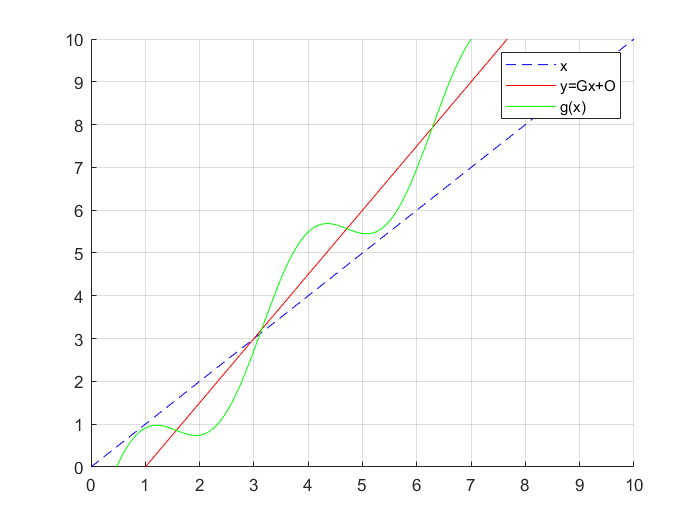

axis([0 10 0 10]) %range of vision of the axes
legend('x','y=Gx+O','g(x)') %legend

## Uncertainty of a measure

disp('========================');

disp('Uncertainty of a measure');

Incertezza di una misura


disp('========================');

y=input('Measured value: ');
disp('Measured value: ');

Valore misurato:


disp(y);

    -4



r_u_g=input('Relative uncertainty of gain: ');
disp('Relative uncertainty of earnings: ');

Incertezza relativa di guadagno:


disp(r_u_g);

     1



o_u=input('Offset uncertainty: ');
disp('Offset uncertainty: ');

Incertezza di offset:


disp(o_u);

     7



u_inl=input('Uncertainty of integral nonlinearity: ');
disp('Uncertainty of integral nonlinearity: ');

Incertezza di nonlinearità integrale:


disp(u_inl);

    -3



q_u=input('Quantization uncertainty: ');
disp('Quantization uncertainty: ');

Incertezza di quantizzazione:


disp(q_u);

     0



U=r_u_g*abs(y)+o_u+u_inl+q_u; %uncertainty of a measure
disp('Measurement uncertainty: ');

Incertezza di misura:


disp(U);

     8

